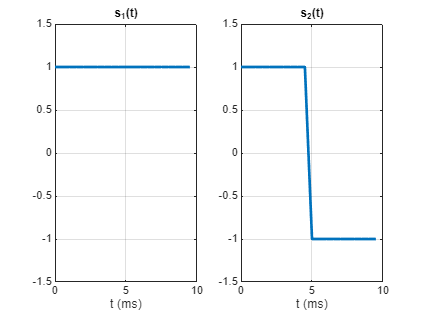

%% PARÁMETROS DEL SISTEMA
clear; close all; clc;

T  = 10e-3;      % Periodo de símbolo (10 ms)
Ts = T / 20;     % Periodo de muestreo (0.5 ms)
N  = 6;          % Número de símbolos a transmitir

%% EJERCICIO 1.1: SEÑALES BASE Y MODULACIÓN
% 1. Generar s1(t) y s2(t)
[s1, s2, t] = generar_senales_fig1(T, Ts);

% Gráfica de la Figura 1
figure;
subplot(1,2,1);
plot(t*1e3, s1, 'LineWidth', 2); grid on;
title('s_1(t)'); xlabel('t (ms)'); ylim([-1.5 1.5]);

subplot(1,2,2);
plot(t*1e3, s2, 'LineWidth', 2); grid on;
title('s_2(t)'); xlabel('t (ms)'); ylim([-1.5 1.5]);


% 2. Generar vector aleatorio X con valores en [+1, -1]
alfabeto = [1, -1];
X = alfabeto(randi(2, 1, N));
disp('Símbolos generados X =');

Símbolos generados X =


disp(X);

    -1    -1     1    -1    -1     1



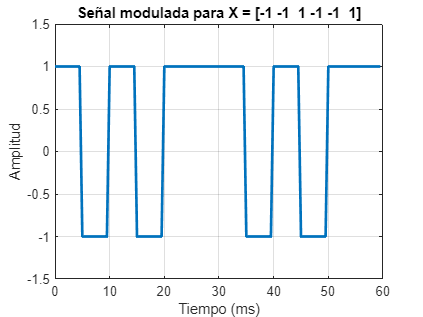


% 3. Concatenar señales y representar
[s_tx, t_tx] = modular_secuencia(X, s1, s2, Ts);

figure;
plot(t_tx*1e3, s_tx, 'LineWidth', 2); grid on;
xlabel('Tiempo (ms)'); ylabel('Amplitud');
title(['Señal modulada para X = [', num2str(X), ']']);
ylim([-1.5 1.5]);


%% EJERCICIO 2.1: BASES ORTONORMALES
[phi1, phi2, a1, a2] = calcular_bases(s1, s2, Ts);

fprintf('a1 = %.2f (Teórico: 1/sqrt(T) = %.2f)\n', a1, 1/sqrt(T));

a1 = 10.00 (Teórico: 1/sqrt(T) = 10.00)


fprintf('a2 = %.2f (Teórico: 1/sqrt(T) = %.2f)\n', a2, 1/sqrt(T));

a2 = 10.00 (Teórico: 1/sqrt(T) = 10.00)



% Comprobación rápida de ortogonalidad (debe dar 0)
producto_escalar = sum(phi1 .* phi2) * Ts;
fprintf('Producto escalar <phi1, phi2> = %.2e\n', producto_escalar);

Producto escalar <phi1, phi2> = 0.00e+00
